clear
close all
clc

D = 2;

lb = -2*ones(1,D);
ub = 2*ones(1,D);

tic

V0 = lb + (ub - lb).*lhsdesign(D,1)';

%diffgrad

V = V0;

opt1 = optim.diffGrad(V,'lr',0.05);

for i = 1:2000
    
    Vi(:,i) = V;

    [e(i),dV] = testFuncs.Rosenbrock(V,1);
    [opt1,V] = opt1.step(V,dV);
    
end

time_diffgrad = toc

time_diffgrad = 0.7002


V1 = Vi;
e1 = e;

%AdamLS

V = V0;

opt2 = optim.AdamLS(V);
FF = @(x) testFuncs.Rosenbrock(x,1);

for i = 1:2000
    
    Vi(:,i) = V;

    [e(i),dV] = testFuncs.Rosenbrock(V,1);
    [opt2,V] = opt2.step(V,FF,dV);
    
end

time_AdamLS = toc

time_AdamLS = 1.4728


V2 = Vi;
e2 = e;

%PSO

V = V0;

opt3 = optim.PSO(10,V);
FF = @(x) testFuncs.Rosenbrock(x,1);

for i = 1:2000
    
    Vi(:,i) = V;

    [opt3,V,e(i)] = opt3.step(FF);
    
end

time_PSO = toc

time_PSO = 1.6621


V3 = Vi;
e3 = e;

%FD_Grad

V = V0;

opt4 = optim.FD_Grad(V,10);
FF = @(x) testFuncs.Rosenbrock(x,1);

for i = 1:2000
    
    Vi(:,i) = V;

    [opt4,V,e(i)] = opt4.step(FF);
    
end

time_FD_Grad = toc

time_FD_Grad = 2.1396


V4 = Vi;
e4 = e;

%CMAES

V = V0;

opt5 = optim.CMAES(D,10);
FF = @(x) testFuncs.Rosenbrock(x,1);

for i = 1:2000
    
    Vi(:,i) = V;

    [opt5,V,e(i)] = opt5.step(FF);
    
end

time_CMAES = toc

time_CMAES = 2.7133


V5 = Vi;
e5 = e;

%Adam

V = V0;

opt6 = optim.Adam(V,'lr',0.05);

for i = 1:2000
    
    Vi(:,i) = V;

    [e(i),dV] = testFuncs.Rosenbrock(V,1);
    [opt6,V] = opt6.step(V,dV);
    
end

time_Adam = toc

time_Adam = 3.4940


V6 = Vi;
e6 = e;

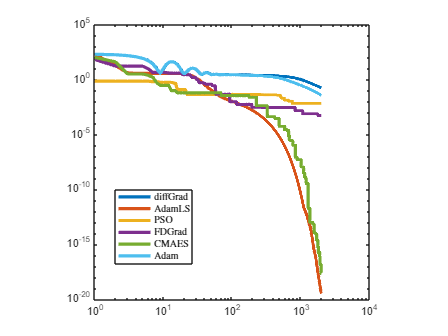

figure
hold on
plot(e1,'LineWidth',3)
plot(e2,'LineWidth',3)
plot(e3,'LineWidth',3)
plot(e4,'LineWidth',3)
plot(e5,'LineWidth',3)
plot(e6,'LineWidth',3)
set(gca,'xscale','log')
set(gca,'yscale','log')
axis square
box on
legend('diffGrad','AdamLS','PSO','FDGrad','CMAES','Adam','interpreter','latex', "Position", [0.2577 0.2157 0.1724, 0.2208])

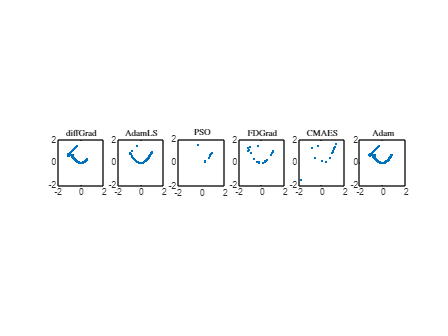


figure
subplot(1,6,1)
plot(V1(1,:),V1(2,:),'.')
axis([-2 2 -2 2])
axis square
title('diffGrad','interpreter','latex')

subplot(1,6,2)
plot(V2(1,:),V2(2,:),'.')
axis([-2 2 -2 2])
axis square
title('AdamLS','interpreter','latex')

subplot(1,6,3)
plot(V3(1,:),V3(2,:),'.')
axis([-2 2 -2 2])
axis square
title('PSO','interpreter','latex')

subplot(1,6,4)
plot(V4(1,:),V4(2,:),'.')
axis([-2 2 -2 2])
axis square
title('FDGrad','interpreter','latex')

subplot(1,6,5)
plot(V5(1,:),V5(2,:),'.')
axis([-2 2 -2 2])
axis square
title('CMAES','interpreter','latex')

subplot(1,6,6)
plot(V6(1,:),V6(2,:),'.')
axis([-2 2 -2 2])
axis square
title('Adam','interpreter','latex')